# Runge-Kutta Order 4

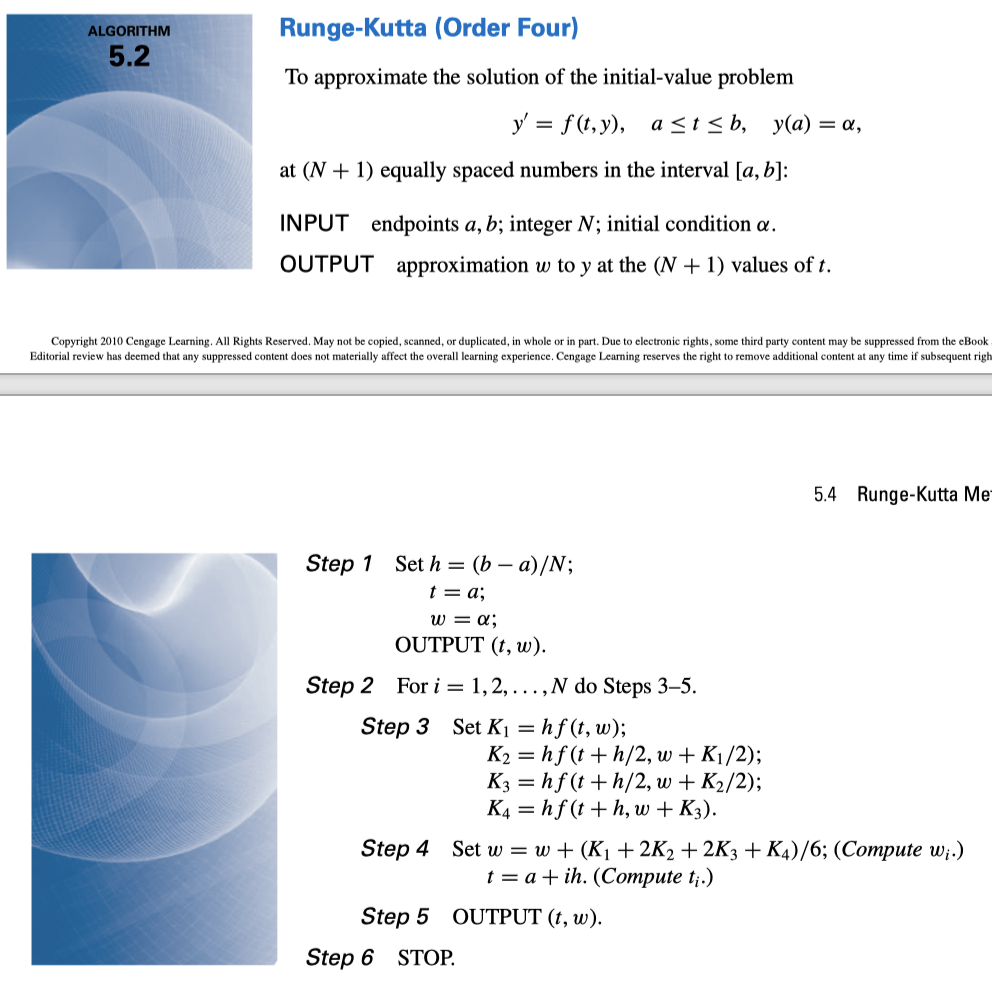

## Initialization

clc; clear; close all; %initialization

## Input the data

a=0; %input the left endpoint
b=2; %input the right endpoint
ya=0.5; %input the initial value on y(a)
N=10; %input the number of space
f=@(t,y) y-t^2+1;           %f



## Computation

h=(b-a)/N;
t=[];
w=[];



t(0 +1)=a;
w(0 +1)=ya;
for i=1:1:N
    t(i +1)=a+i*h;

    k1=h*f(t(i-1 +1),w(i-1 +1));
    k2=h*f(t(i-1 +1)+h/2,w(i-1 +1)+1/2*k1);
    k3=h*f(t(i-1 +1)+h/2,w(i-1 +1)+1/2*k2);
    k4=h*f(t(i-1 +1) + h,w(i-1 +1)+k3);

    w(i +1)=w(i-1 +1)+1/6*(k1+2*k2+2*k3+k4);
    
end

